clear all;
close all;
clc;

## Import image

image=imread(['C:\Users\home\Google Drive\Masterarbeit\Camera Measurements\' ...
    'TriangulationMeasurementNew\rep200.png']);
%Macwin
% image=imread(['C:\Users\Daniel\Google Drive\Masterarbeit\Camera Measurements' ...
%    '\TriangulationMeasurementNew\rep201.png']);
n=43;
%Mac
%image=imread(['/Users/daniel/Google Drive/Masterarbeit' ...
%    '/Camera Measurements/TriangulationMeasurement/rep1.png']);

## Cutting image and thresholding

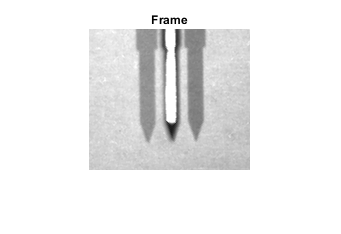

%binarize settings 1-22 left=0.56 right=0.58 probe=0.5
%                  230-251 left=0.52 right=0.56 probe=0.49
minobjectsize=30;

%Large frame
Frame=imsharpen(image(435:575,575:735)); %y141,x161
imshow(Frame);
title('Frame');

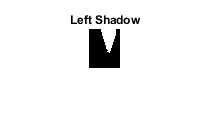


%left shadow
leftshadow=imsharpen(Frame(90:128,40:70));
%imshow(leftshadow);
leftshadowbin = imbinarize(leftshadow,0.64);%from180 0.65 else 0.75
invleftshadowbin=imcomplement(leftshadowbin);
leftshprep = bwareaopen(invleftshadowbin,minobjectsize); %filter small objects
imshow(leftshprep);
title('Left Shadow');

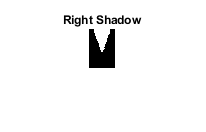


%right shadow
rightshadow=imsharpen(Frame(90:128,95:120));
%imshow(rightshadow);
rightshadowbin = imbinarize(rightshadow,0.7);  % from180 0.65 else 0.75
invrightshadowbin=imcomplement(rightshadowbin);
rightshprep = bwareaopen(invrightshadowbin,minobjectsize); %filter small objects
imshow(rightshprep);
title('Right Shadow');

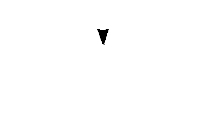


%probe
Probesharpened= imsharpen(Frame(95:130,70:100));
probeshadow=imadjust(Probesharpened,[0.33 0.4]);
%localcontrast(
imshow(probeshadow);

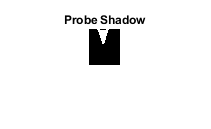

probeshadowbin = imbinarize(probeshadow,0.4); % from 180 0.3
invprobeshadowbin=imcomplement(probeshadowbin);
probeshprep = bwareaopen(invprobeshadowbin,minobjectsize); %filter small objects
imshow(probeshprep);
title('Probe Shadow');

## Locate tip point of left shadow

%Left shadow
[lrow,lcol]=size(leftshprep);

for i=1:1:lrow-1
    rowsum=sum(leftshprep(i,1:lcol));
    if rowsum==0
        rowsum=100;
    end
    lsumvector(i,1)=rowsum;
end
[lM,lrowlocation] = min(lsumvector);

switch lM
    case 1
    [lrow,lcolocation] = find(leftshprep(lrowlocation,:),1);
    case 2
    [lrow,lcolocation] = find(leftshprep(lrowlocation,:),1);
    lcolocation=lcolocation+0.5;
    case 3
    [lrow,lcolocation] = find(leftshprep(lrowlocation,:),1);
    lcolocation=lcolocation+1;
    case 4
    [lrow,lcolocation] = find(leftshprep(lrowlocation,:),1);
    lcolocation=lcolocation+1.5;
    case 5
    [lrow,lcolocation] = find(leftshprep(lrowlocation,:),1);
    lcolocation=lcolocation+2;
end
lcolocation

lcolocation = 21

lrowlocation

lrowlocation = 24

## Locate tip point of right shadow

%Right shadow
[rrow,rcol]=size(rightshprep);

for i=1:1:rrow-1
    rowsum=sum(rightshprep(i,1:rcol));
    if rowsum==0
        rowsum=100;
    end
    rsumvector(i,1)=rowsum;
end
[rM,rrowlocation] = min(rsumvector);

switch rM
    case 1
    [rrow,rcolocation] = find(rightshprep(rrowlocation,:),1);
    case 2
    [rrow,rcolocation] = find(rightshprep(rrowlocation,:),1);
    rcolocation=rcolocation+0.5;
    case 3
    [rrow,rcolocation] = find(rightshprep(rrowlocation,:),1);
    rcolocation=rcolocation+1;
    case 4
    [rrow,rcolocation] = find(rightshprep(rrowlocation,:),1);
    rcolocation=rcolocation+1.5;
end
rrowlocation

rrowlocation = 22

rcolocation

rcolocation = 13.5000

## Locate tip point of probe shadow

%Right shadow
[prow,pcol]=size(probeshprep);

for i=1:1:prow-1
    rowsum=sum(probeshprep(i,1:pcol));
    if rowsum==0
        rowsum=100;
    end
    psumvector(i,1)=rowsum;
end
[pM,prowlocation] = min(psumvector);

switch pM
    case 1
    [prow,pcolocation] = find(probeshprep(prowlocation,:),1);
    case 2
    [prow,pcolocation] = find(probeshprep(prowlocation,:),1);
    rcolocation=rcolocation+0.5;
    case 3
    [prow,pcolocation] = find(probeshprep(prowlocation,:),1);
    pcolocation=pcolocation+1;
    case 4
    [prow,pcolocation] = find(probeshprep(prowlocation,:),1);
    pcolocation=pcolocation+1.5;
end
prowlocation

prowlocation = 15

pcolocation

pcolocation = 14

## Reference position

%pixel/mm conversion 1128px pro 80 mm
pixpermm=1065/75; %1071/75
%Reference location, first location in Frame
%Left shadow
lrefcol=20+40;%18+40;
lrefrow=25+90;%23+90;
%right shadow
rrefcol=12.5+95;%11+95;
rrefrow=23+90;%21+90;
%probe shadow
prefcol=14+70;%14+70;
prefrow=16+95;%24+90;
%distance bewteen shadows
refdist=sqrt(((lrefcol-rrefcol)^2)+((lrefrow-rrefrow)^2)) %in pix

refdist = 47.5421

refdistmm=refdist/pixpermm % in mm

refdistmm = 3.3480

%probe reference height
light_height = 183;
light_diameter= 53;
light_distance=light_diameter/2;
Shadowlength=refdistmm/2;
Refprobeheight=(light_height*Shadowlength)/(light_distance+Shadowlength) % in mm

Refprobeheight = 10.8733

## Positions of image

%left
lcolpose=lcolocation+40;
lrowpose=lrowlocation+90;
%right
rcolpose=rcolocation+95;
rrowpose=rrowlocation+90;
%probe
pcolpose=pcolocation+70;
prowpose=prowlocation+95;
% probe height
imdist=sqrt(((lcolpose-rcolpose)^2)+((lrowpose-rrowpose)^2)) %in pix

imdist = 48.0416

imdistmm=imdist/pixpermm % in mm

imdistmm = 3.3832

imShadowlength=imdistmm/2;
improbeheight=(light_height*imShadowlength)/(light_distance+imShadowlength) % in mm

improbeheight = 10.9807

% X and Y distances
im_xdistmm=(prefcol-pcolpose)/pixpermm %in mm

im_xdistmm = 0

im_ydistmm=(prefrow-prowpose)/pixpermm % in mm

im_ydistmm = 0.0704

im_zdistmm=(Refprobeheight-improbeheight) % in mm

im_zdistmm = -0.1074

## Distance in 3D

ref3d=[0,0,0]'

ref3d =      0
     0
     0


im3d=[im_xdistmm,im_ydistmm,im_zdistmm]'

im3d =          0
    0.0704
   -0.1074


d = norm(ref3d-im3d)

d = 0.1284

## Plot Result

%distances MacWin
%load('C:\Users\Daniel\Google Drive\Masterarbeit\Camera Measurements\TriangulationMeasurementNew\points.mat')
%load('C:\Users\Daniel\Google Drive\Masterarbeit\Camera Measurements\TriangulationMeasurementNew\distances.mat')
load('distances.mat')
load('points.mat')

%resultdist(1,n)=d;
%save('distances.mat','resultdist'); %resultdist(1,n)
%resultpoints(n,1:3)=im3d';
%save('points.mat','resultpoints');

%save(['path/X_' num2str(j) '.mat'],'X')


%xaxis=[1,2,3,4,5,6,7,8,9,10,11,12,13,14,15,16,17,18,19,20,21,22,230,231,232,234,235,236,237,237,239,240,241,242,243,244,245,246,247,248,249,250,251];
%yaxisdist=[0,]
%3D Points
%resultdist=[0];

%plot3([0 1],[-0.0709 2],[-0.0934 3],'x')
%grid on
%axis([-1 1 -1 1 -1 1])


## Detected points in initial frames

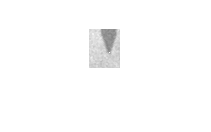

leftshadow(lrowlocation,round(lcolocation))=250;
 imshow(leftshadow)

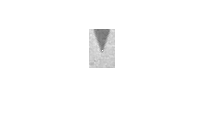

rightshadow(rrowlocation,round(rcolocation))=250;
imshow(rightshadow)

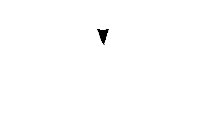

probeshadow(prowlocation,round(pcolocation))=250;
imshow(probeshadow)